# Support Vector Machines (SVM) Model: ARMA-Linear

## Setup:

**Configurate the path and clear the workspace, etc.**

clc; close al l; clear;
addpath(genpath(fullfile('../')));

## Input model:

***The input features are described as the power levels found at each frequency bin***

***Select order of AR and MA model:***

p = 12;
q = 12;

***Select IR set for augmentation:***

nameIRms = "IR44K_2s_1000ms";

fs = 44100;
IRLen = 40;
dir = "aux_data/IR_Z_fixed/2s/"; % Azimuth
IRms = struct2cell(load(dir+nameIRms));
IRms = IRms{1};
IRms =IRms(:,2);
IRms = [IRms{:}];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%               Prepare Bands           %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Calculate Third Octave Bands (base 2) 
octaves = 3;
N_bands = ceil(32*(octaves/3));
bands = zeros(N_bands,3);
start_band =floor(18*(octaves/3));
end_band = N_bands-start_band-1;
bands(:,2)  = 10^3 * (2 .^ ([-start_band:end_band]/octaves));
fd = 2^(1/(octaves*2));
bands(:,3) = bands(:,2).* fd;
bands(:,1) = bands(:,2) ./ fd;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

nfft = 8192;
N_bins = N_bands;
df = fs/(2*((nfft/2)+1));
f = 0:df:(fs-df)/2;
f_2_5k = ceil(2500/(fs/(N_bins*2)));
f_20k = ceil(20000/(fs/(N_bins*2)));


N_noise_samples = 50;
N_augmentations = N_noise_samples*IRLen;% 100 noise samples * 40 augmentations = 4000 augmented samples

x_train = zeros(N_bins,N_augmentations);
y_train = zeros(N_augmentations,1);
vec = [1:6, 36:40; 6:16; 16:26; 26:36];
designSpecs = fdesign.lowpass('Fp,Fst,Ap,Ast', 20000, 22050, 0.01, 80, fs);
F = design(designSpecs);
for k = 1:N_noise_samples
    for i = 1:40
        % Augment noise sample
        noise = randn(fs,1);
        noise = filter(F,noise);
        index = ((k-1)*40) + i;
        noise_aug = conv(noise, IRms(:,i), 'same');
       
        % Get parameters of autoregressive filter
        [ar_params, e] = aryule(noise_aug,p); % Get parameters of Autoregressive part
        
        % Filter original time-series
        v_n = filter(1,ar_params,noise_aug);
        v_n = v_n(p:end);
        
        % Get parameters of moving average filter
        co_a = aryule(v_n,q*2);     % Approximate MA model using a Long-AR model (recommended to take order 2*Q)
        ma_params = aryule(co_a,q);
       
        H = freqz(ma_params,ar_params,nfft,"whole", fs);
        H_oneside = H(1:nfft/2 +1);
        Sxx = e.*(abs(H_oneside).^2);
        Pxx = Sxx./fs;
        Pxx = normalize(Pxx,'range');
        
        for t = 1:N_bands
            x_train(t,index) = mean(Pxx(f>= bands(t,1) & f <= bands(t,3)));    % Band-average without window
        end
        y_train(index) = find(any(i==vec,2),1);
    end
end
directions = ["Front"; "Left"; "Back"; "Right"];
y_train = categorical(directions(y_train));

***Train***

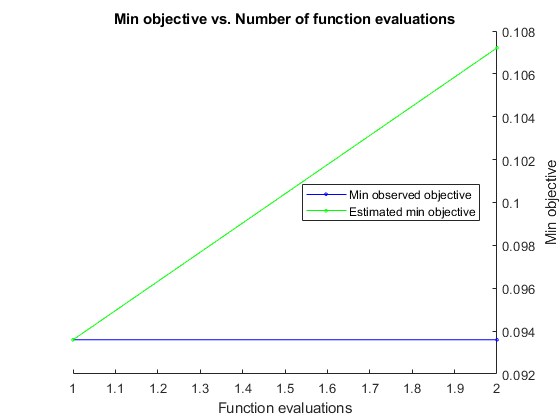

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Coding | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |    0.093596 |      2.9402 |    0.093596 |    0.093596 |     onevsone |        294.1 |      0.33828 |
| 

% Rename variables for clarity:
%   X: Predictor data (rows are observations)
%   Y: Response data
X = x_train'; 
Y = y_train;

% Ensemble template 
tTree = templateTree('surrogate','on');
tEnsemble = templateEnsemble('GentleBoost',100,tTree);

Mdl = fitcecoc(X,Y,'Coding',"onevsall",'Learners','svm', "Prior","uniform", "OptimizeHyperparameters","auto",...
    "HyperparameterOptimizationOptions",struct('AcquisitionFunctionName','expected-improvement-plus'));

## Evaluation

% Compute resubstitution classification error to obtain training error 
train_error = resubLoss(Mdl, 'lossfun', 'classiferror');
disp("Training error: " + train_error*100 + "%");
% Cross-validate classifier
CVMdl = crossval(Mdl);
% Compute cross-validation classification error: 
cv_error = kfoldLoss(CVMdl, 'lossfun','classiferror');

disp("Validation error: " + cv_error*100 + "%");

***Case 1: Low errors***

***    If the validation error is higher than the training error this indicates that there is a case of HIGH VARIANCE***

***    High variance can be solved by adding more training data***

***Case 2: High errors***

***    If both the validation and training error are high this indicates a case of HIGH BIAS***

***    High bias asks for more distinct features***

## Test on same reverberation duration

***Augment test samples***

N_tests = 10;
N_augmentations = N_tests*IRLen;% 100 noise samples * 40 augmentations = 4000 augmented samples

x_test = zeros(N_bins,N_augmentations);
y_test = zeros(N_augmentations,1);

for k = 1:N_tests
    for i = 1:40
        % Augment noise sample
        noise = randn(fs,1);
        noise = filter(F,noise);
        index = ((k-1)*40) + i;
        noise_aug = conv(noise, IRms(:,i), 'same');
       
        % Get parameters of autoregressive filter
        [ar_params, e] = aryule(noise_aug,p); % Get parameters of Autoregressive part
        
        % Filter original time-series
        v_n = filter(1,ar_params,noise_aug);
        v_n = v_n(p:end);
        
        % Get parameters of moving average filter
        co_a = aryule(v_n,q*2);     % Approximate MA model using a Long-AR model (recommended to take order 2*Q)
        ma_params = aryule(co_a,q);
       
        H = freqz(ma_params,ar_params,nfft,"whole", fs);
        H_oneside = H(1:nfft/2 +1);
        Sxx = e.*(abs(H_oneside).^2);
        Pxx = Sxx./fs;
        Pxx = normalize(Pxx,'range');
        
        for t = 1:N_bands
            x_test(t,index) = mean(Pxx(f>= bands(t,1) & f <= bands(t,3)));    % Band-average without window
        end
        y_test(index) = find(any(i==vec,2),1);
    end
end
directions = ["Front"; "Left"; "Back"; "Right"];
y_test = categorical(directions(y_test));

***Predict test samples***

y_pred = predict(Mdl,x_test');
y_pred(randsample(numel(y_pred),5))
%numMisclass = sum(~strcmp(,species(idxVal)));
test_error = 1-sum(y_pred==y_test)/N_augmentations;
disp("Test error: " + test_error*100 + "%");

